# Module 1 

**Introduction to Systems and Systems Engineering**

[**< Previous**](matlab:open('./QuickStart.mlx'))**,  **[**Module 1**](matlab:open('./Module1.mlx'))**, **[**Module 2**](matlab:open('./Module2.mlx'))**,  **[**Module 3**](matlab:open('./Module3.mlx'))**, **[**Module 4**](matlab:open('./Module4.mlx'))**, **[**Module 5**](matlab:open('./Module5.mlx'))**,  **[**Next >**](matlab:open('./Module2.mlx'))

## **1. What Is ****A**** System?** 

According to the International Council on Systems Engineering (INCOSE) Technical Product, “a system is an arrangement of parts or elements that together exhibit behavior or meaning that the individual constituents do not.” Moreover, the U.S. Department of Defense Architecture Framework defines the term system as “any organized assembly of resources and procedures united and regulated by interaction or interdependence to accomplish a set of specific functions.“Also, according to the NASA Systems Engineering Handbook (V. 2), “a system is the combination of elements that function together to produce the capability required to meet a need.” As seen, there are various definitions of the term “system” in the systems engineering literature. However, there are clear commonalities among these definitions.

The term element in the definitions above refers to hardware, software, processes, procedures and techniques, facilities, services, and basically all supporting resources/components required to meet a set of needs and achieve the objective(s) of the system. Moreover, all the elements of a system must be interconnected, interrelated, and function together in a meaningful way to achieve some common objective(s). According to the INCOSE Technical Product, the elements in a system are arranged such that together they exhibit a behavior that the individual elements cannot show alone. This implies that a system as an individual whole is more than the sum of its elements. 

Some examples of a system include the human body, a river system, a vehicle, a university, the government, a software program, a space shuttle, a car production facility, or a ground transportation system. For example, in a ground transportation system, some of the system elements include taxicabs, passenger cars, buses, metro infrastructure, trains, railroads, highways, toll roads, streets, transportation rules/guidelines, and people. All these elements are interconnected and work coherently together to achieve some common objectives such as the transportation of people and goods from one point to another, enhancing people's quality of life, strengthening urban functions, and facilitating industrial economic activities.

As another example, consider a car production facility. Some of the elements of this system include different machines on the production line, conveyors, forklifts, buildings, inventory of parts and raw materials, inventory management plans, shipment trucks, and people. This facility uses a set of raw materials, skilled workers, and all supporting resources (elements) to manufacture ready-to-drive safe, reliable, and high-quality cars and to also generate revenue.

## **2. Systems Thinking** 

Systems thinking is a mindset, a perspective, a holistic approach for analyzing a problem where the problem in hand is seen as the outcome of interaction among a set of elements and factors. Instead of looking at each element and its relation to the problem in isolation, one must understand how the individual elements interact and function together to make up the big picture. This may not be so obvious but improving the functioning of one of the elements of a system may not necessarily improve the performance of the whole system. Any improvement proposal should not miss the effect of interrelation and interaction among the elements within a system. Instead, it must adopt a system perspective and look at the system as a whole. 

As an example, imagine we need to improve the production rate (i.e., the number of cars produced in a day) in the car production facility discussed before. To this end, engineers may improve the performance of one of the manufacturing machines on the production line. However, this change may lead to the creation of a bottleneck at a different point on the production line. Thus, it may not improve the production rate of the production facility. This example shows that in order to improve the performance of a system one has to adopt a system perspective and look at all elements of the system and their interrelation/functioning together as a whole, as opposed to focusing on improving some of the elements of the system in isolation.   

## **3. System Behavior ** 

System behavior or system dynamics can be defined as “what” a system is expected to do in response to its external environment and/or various types of triggers as well as “how well” a system must perform those functions. For example, in the car production facility example, being able to reliably produce cars in response to customer demands and given the availability of resources is the expected behavior. However, this production facility needs to be designed such that the customer demand can be met in a timely manner using the minimum amount of resources/cost. So, the answer to the question “what this system is expected to do” is “meeting the customer demands given the availability of resources”. Moreover, the answer to the question “how well these functions are expected to be performed” is “timely with minimum cost”. 

### 3.1. System Behavior Example

We can focus on a simple example to better understand the system's behavior. In general, systems that are considered under the framework of Systems Engineering are very complex and include a variety of behaviors, as we will learn in subsequent modules.

To understand simple system behavior, consider a black box system that receives an input and returns a sinusoidal signal as the output $\Rightarrow \textrm{Output}=\left(\textrm{Amp}\right)\times \;\sin \left(2\times \pi \times \textrm{time}\;\right)$

The inputs determine the amplitude of the output signal. If the user changes the input, the output will change accordingly. This is a behavior of the system and what we expect to see as the output.

Let's also add a condition (or trigger). We assume that the system ensures the amplitude never exceeds a threshold (in this example, 10 units). If the user input creates a scenario that exceeds the maximum allowable amplitude, the system shuts down the output signal and returns a zero. We can use MATLAB to model this behavior.

We only need to focus on the inputs and outputs for system behavior. We do not need to know the inside of the black box. Use the amplitude controller to change the input and see how the output changes.

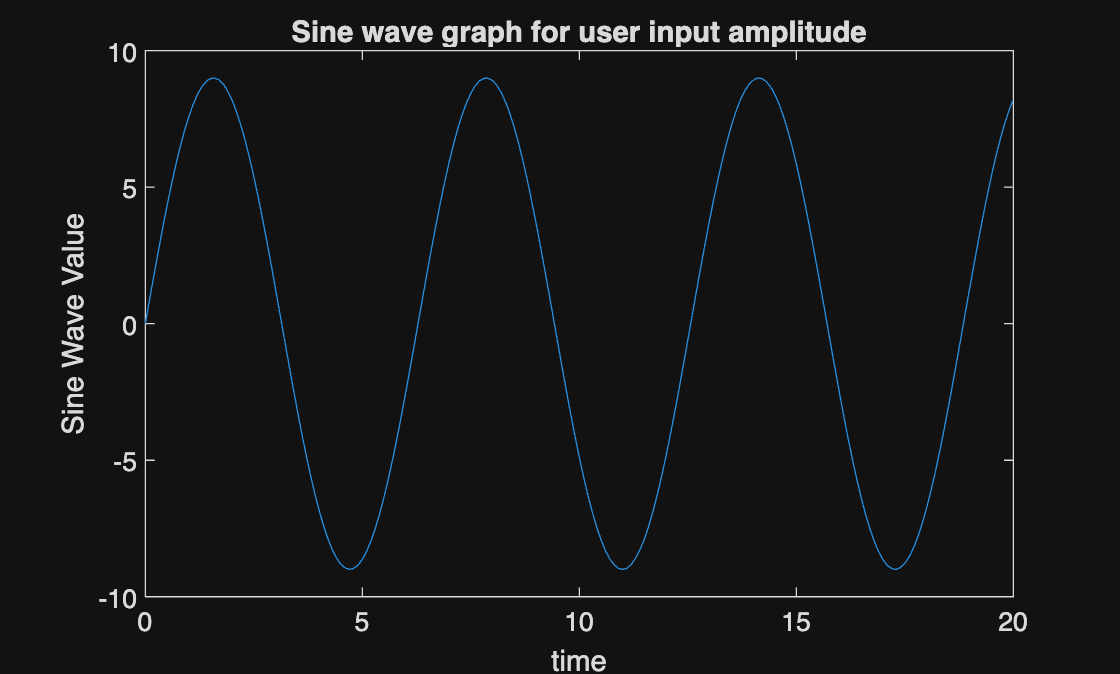

useramp = 9;
[~, lastBit] = fileparts(pwd);
if string(lastBit) == "FFCS System Composer Consolidated"
    cd('..')
end

outsig = sim("Simple Example/module1example.slx");
plot(outsig.tout,outsig.yout{1}.Values.Data)
xlabel("time")
ylabel("Sine Wave Value")
title("Sine wave graph for user input amplitude")

## **4. System Structure** 

The structure of a system represents a logical organization or configuration of its elements, the attributes and characteristics of those elements, as well as the relationships and interconnections among those elements such that the system of interest can generate its expected behavior. There is a strong relation between the structure of a system and its observed behavior. Any change in the structure of a system leads to a change in its behavior. To change the behavior of a system, the system structure needs to be changed. In the process of designing and developing any system, one needs to first understand the desired/expected system behavior. Next, the system components must be designed and configured such that the final system structure can generate the desired system behavior. In other words, the structure of a system tends to follow the system’s behavior during development, not the other way around. 

Going back to the car production facility example, to establish the desired behavior (e.g., having a consistent and reliable production rate of 50 cars per day), the designers must decide on the type and number of manufacturing machines needed, the size and number of the manufacturing buildings, the layout of those machines on the manufacturing floor (layout of the production line), the level of inventory of various parts and raw material to be kept in warehouses, the number and skill of workers needed as well as their allocation to the production line, number of forklifts, conveyors, and other support equipment, to name a few. So, the design and development of the structure of the manufacturing facility are performed such that the specified production rate can be achieved when the system is up and running. A change in any of these components, for example, a change in the inventory level of parts and raw materials or a change in the number of workers on the production line, can potentially lead to a change in the production rate of the facility (i.e., expected behavior). 

Throughout this handbook, we will implement the learnings of each module on a model of a public transportation system. In a public bus transportation system, the desired system behavior can be defined as safe, convenient, and timely transportation of 100% of passengers across the city with less than 10 minutes of average waiting time for passengers in the bus stations. Some of the aspects of the system structure that can affect the system behavior are the number and specification of buses, the number, and location of bus stations, the number and location of maintenance hubs, the inventory of spare parts, the number of drivers, the number of maintenance staff, the bus transportation routes among stations, maintenance plan, and bus schedule, etc.

### 4.1. System Structure Example

Returning to the Sine Wave example discussed in Section 3.1, the internal structure of the system is illustrated inside the black box diagram shown below. This model provides a clearer understanding of how various components work together to produce the system's behavior.

Key components of the system include:

- **Switch Check** – evaluates whether the input conditions satisfy specific criteria for passing a signal forward.

- **Sine Wave Generator** – produces a continuous sinusoidal signal that serves as a key input.

- **Amplitude Threshold** – defines a cutoff level to determine whether the incoming signal is strong enough to trigger further processing.

- **Output Segment** – receives the final processed signal and sends it to be printed or displayed.

These four elements serve as the building blocks of the system and are integrated within the black box. If the signal is below the threshold, it is multiplied by the sine wave produced by the generator according to the formula below:


$$\Rightarrow \textrm{Output}=\left(\textrm{Amp}\right)\times \;\sin \left(2\times \pi \times \textrm{time}\;\right)$$


The resulting signal is then passed to the output segment, which delivers the final output as shown in the figure below.

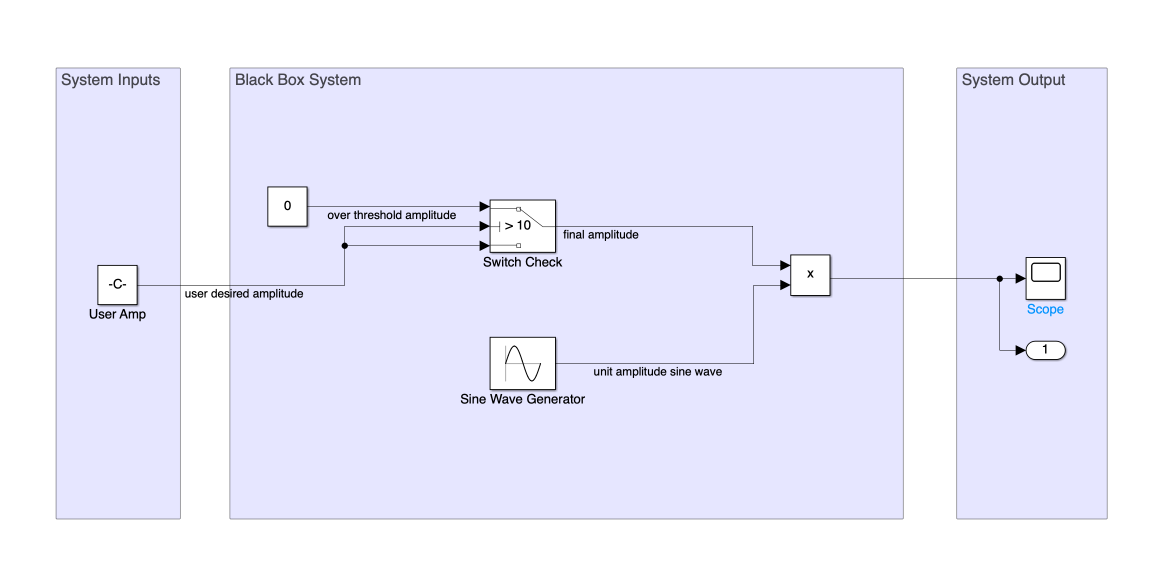  

You can open this Simulink model by clicking on the button below and changing or exploring the model.

 
[~, lastBit] = fileparts(pwd);
if string(lastBit) == "FFCS System Composer Consolidated"
    cd('..')
end
open_system("Simple Example/module1example.slx")

## **5. Systems**** Engineering** 

According to the International Council on Systems Engineering Technical Product, “Systems engineering is a transdisciplinary and integrative approach to enable the successful realization, use, and retirement of engineered systems, using systems principles and concepts, and scientific, technological, and management methods.” Moreover, NASA Systems Engineering Handbook (V. 2) defines systems engineering “as a methodical, multi-disciplinary approach for the design, realization, technical management, operations, and retirement of a system.”

Some important concepts stand out in these definitions. First, systems engineering is an approach, a process, a methodology, or, in other words, a logical way of thinking. Moreover, systems engineering is an interdisciplinary approach that brings together various engineering and science disciplines to effectively design and develop a system that can address the needs of stakeholders. Systems engineering methodology encompasses both technical and managerial processes (set of activities) that enable the successful realization, use, and retirement of any system. Management processes support the technical processes through various planning operations such as time management, resource management, and risk management, to name a few.

All the activities that should be performed for a system to be accomplished, form the system “life cycle”. Depending on the goals of these activities in the system life cycle and their relations, they can be categorized into "phases” or “stages” such as the design phase, production phase, or maintenance phase. Each phase has a specific purpose and contribution to the entire system life cycle. Breaking down the activities of the system life cycle into phases organizes the entire process into more manageable pieces. Systems engineering framework makes sure a system goes through its entire life cycle effectively and efficiently. 

Here, as a frame of reference, we use the major system life cycle phases defined by Blanchard and Fabrycky for a general system. This baseline system life cycle has five phases, namely, conceptual design, preliminary design, detailed design and development, production, operations use, and system support. Each phase in the system life cycle ends with major “go” or “no-go” decisions when the readiness of the project for proceeding to the next phase is comprehensively evaluated by qualified experts and relevant stakeholders. For any particular application, according to the type, complexity, and size of the system of interest being developed, the phases and milestones defined in the baseline system life cycle can be tailored. Some of the industries that have customized the system lifecycle phases and milestones according to their needs are NASA, the U.S. Department of Defense, the U.S. Department of Energy, and the High-Tech Manufacturing industry.

Overall, systems engineering methodology enables the design, development, and utilization of a system while meeting customer requirements safely and in the most cost-effective way. Systems engineering methodology provides an effective way of managing complexity and change in the development of any system. Various studies have shown that as the level of systems engineering efforts in the development of projects increases, the possibility of cost and schedule overruns decreases.

## **6. System Life Cycle Phases** 

The figure below illustrates the major system life cycle phases for a generic system, according to the *NASA Systems Engineering Handbook*. This baseline system life cycle consists of five phases, namely: **Concept and Technology Development, Preliminary Design and Technology Completion, Final Design and Fabrication, System Assembly, Integration, and Test (SAIT), **and** Operations and Sustainment.**

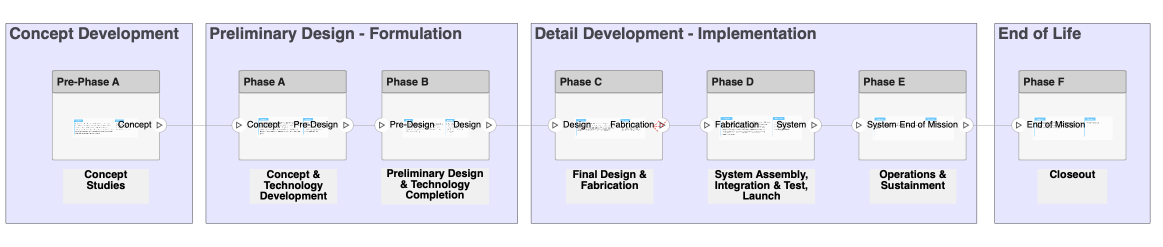

Open this model (designed in System Composer) and explore each phase. 

 
[~, lastBit] = fileparts(pwd);
if string(lastBit) ~= "FFCS System Composer Consolidated"
    cd('.')
end
open_system("Simple Example/module1model.slx")

The “conceptual design phase” starts by understating the mission of the system and extracting the top-level system requirements. The system is then defined in functional terms by identifying a high-level (system-level) set of functions or actions ("whats" ) that should be performed in the system so it can meet its requirements. These system functions are then translated into a high-level (system-level) set of elements or components (“hows”) that are needed to perform those functions. The conceptual design phase at the end leads to the development of the initial system-level (top-lvel) architecture or configuration of the system.

The “preliminary design phase” focuses on refining the initial system-level architecture (developed in the conceptual design phase) and partitioning the system-level components into lower-level components. In this phase, through a top-down iterative process, the system-level functions or "whats" are broken down into a lower-level (more detailed) set of functions. The functional architecture of the system is used to identify the resources required to perform those functions. The more detailed set of functions or "whats" as well as their required resources are then translated into a more detailed set of components or “hows” that can perform those functions. The preliminary design phase at the end leads to the development of the physical architecture or configuration of the system.

The “detailed design phase” focuses on the realization of the system as idetifined through the physical architecture. Using a bottom-up approach, the lower-level system components are realized and integrated into higher-level components and ultimately into the prototype of the whole system. The developed prototype is extensively verified and evaluated before transitioning to the “production” phase. The rest of the system life cycle focuses on the activities related to system production, utilization, and maintenance. 

## **7. Document-Based Systems Engineering**** Approach** 

In the systems engineering process discussed above the output of the systems engineering activities (i.e., requirements, functional architecture, physical requirements, etc.) are usually documented in a hard-copy or electronic file format in text descriptions and/or graphical depictions, that are then communicated among designers, developers, reviewers, customers, users and other stakeholders, as appropriate. A significant level of effort and various management tools are needed to ensure these documents are complete, consistent, and tractable; for example, to trace the requirements among different design specification documents to ensure they have been met. Thus, in a document-based systems engineering approach, the assessment of completeness, consistency, and relationships between requirements and design decisions is a rigorous and difficult process. Moreover, assessing and tracing the impact of any change in requirements and/or design decisions on various aspects of the system proves to be difficult and can negatively impact the design quality, cost, schedule, as well as customer satisfaction. The solution to this problem is the adoption and use of a Model-Based Systems Engineering approach for the development of engineered systems. 

## **8. Model-Based Systems**** Engineering** 

Model-Based Systems Engineering (MBSE) methodology provides the tools and techniques for developing a set of coherent models to capture the output of systems engineering activities (i.e., requirements, functional architecture, physical requirements, etc.) that were traditionally documented in text descriptions and/or graphical depictions. Consequently, a set of individual models is developed and evolved throughout the system life cycle to capture the system requirements, design logic and specifications, interrelationships, interfaces, test cases, etc. The elements and components of these models can be traced to one another through their relationships, even though they are often presented on different models. This allows for coherent assessment of design decisions and making sure they meet system requirements. The developed models are integrated at the end to form a coherent model of the overall system.

The use of MBSE has several advantages such as the use of a consistent language for describing the problem and the developed solutions, improvement in design quality, improvement in communications among the development team, facilitating the process for assessing if all the system requirements have been addressed, and potentially reusing the subsyste and design artifacts in future projects, if needed.

In the subsequent modules, we go deeper into the set of activities that form the Model-Based Systems Engineering process and the coherent set of models that capture the outcome of those activities as well as their interrelations. 

## **9. Practice Model Introductions**

In this handbook, we focus on demonstrating how to develop Model-Based Systems Engineering artifacts using MATLAB’s System Composer, and map these artifacts to those produced by traditional SE approaches. Each module includes guided examples to help users build system models and understand key MBSE concepts. We will walk through the creation of requirements tables as well as models capturing the functional and physical architecture of the system using the capabilities of System Composer.

For each example, you will build the models step by step. At the end of the module, you’ll have the opportunity to apply what you’ve learned by creating a similar model for a different system. The goal is to compare your self-developed model with a provided solution, helping to reinforce your understanding of MBSE principles and how they can be applied across various contexts.

### **9.1. Guided Example: Fly-by-Wire Flight Control System**

The **Fly-by-Wire Flight Control System** example is based on the architecture of the Airbus A220’s flight control system. This system’s mission is to provide safe and efficient navigation for both manual and automated flight modes.

Fly-by-wire systems replace traditional mechanical control linkages with electrical signals transmitted to flight control actuators via computers. This technology offers several advantages, including increased safety, reduced weight, and enhanced system health monitoring, which is why it has become the standard in modern commercial aviation.

In this example, we will model key components and functions of the Fly-by-Wire Flight Control System using System Composer. This will include pilot and environmental inputs, principal electronic components, power control units, and control paths. The model will illustrate how the system monitors performance, indicates maintenance needs, and commands control surfaces for both manual and automated flight control.

This is our guided example which has all details needed to follow the step-by-step implementation of the system in System Composer. 

### **9.2. Practice Example: Online Ordering System**

The **Online Ordering System** example focuses on an e-commerce platform that connects customers with merchants. Its mission is to facilitate online purchases, track orders, and provide a seamless interface for both buyers and sellers. Customers can browse items, place orders, apply discounts, and track deliveries, while merchants can manage their product listings, process orders, and ship items.

In this example, we will develop a software architecture model that represents the various components and interfaces needed for the system’s functionality. The model will detail software modules that manage user accounts, product searches, order processing, and GPS-based delivery tracking. Through this exercise, we will explore how MBSE applies to software systems, connecting hardware interfaces with software architecture. 

For this practice example, we will provide a problem statement and a fully developed model for reference. The objective is for the learners to create their own system model in System Composer based on the problem statement, following the MBSE process outlined in the guided example. By comparing to the reference model, learners can evaluate their understanding of MBSE principles, identify areas for improvement, and gain confidence in developing system models independently.

[**< Previous**](matlab:open('./QuickStart.mlx'))**,  **[**Module 1**](matlab:open('./Module1.mlx'))**, **[**Module 2**](matlab:open('./Module2.mlx'))**,  **[**Module 3**](matlab:open('./Module3.mlx'))**, **[**Module 4**](matlab:open('./Module4.mlx'))**, **[**Module 5**](matlab:open('./Module5.mlx'))**,  **[**Next >**](matlab:open('./Module2.mlx'))